# **Excercise 2: Neuronal Network**

The aim of this second excercise is the classification of real estate with the help of a neuronal network. 

## ***Abstract***

*In excercise two, the task was to train different models using a neural network. The following results were achieved:*

- ***Model 1, Using one layer and multiple features, non regularized: ****In this first model only one layer was chosen, but all features were used. An accuracy of ~70% could be achieved.*

- ***Model 2: Adding additional layer and increase # of hidden units: ****By using an additional layer and a higher number of units, the model could be improved. The accuracy of this second model is in the range of ~71.5%.*

- ***Model 3: Adding third hidden layer and regularization: ****For the third model, an additional third hidden layer was introduced. In order to prevent overfitting, regularization was applied. Thus an accuracy of ~73% could be achieved.*

% Initialization
clear ; close all; clc

## **Develop toolset**

In the following sections we develop different functions which are needed for a neuronal network. The different functions together form a toolset that allows us to build and train our models.

### Load dev data

The data used for the development will be read from a given file *dev*`_data.csv`. As we will split the data later in a training and a cross validation part, we have to randomly order the data. The description of the data and their origin is not part of this assignment. Below the first five rows will be displayed:

% Load dev data
dev_data_ordered = importDevData('dev_data.csv', 5);

ans = 5×4 table
    Var1            X1                    X2             y
    ____    __________________    ___________________    _

     0       0.473382411450517      0.987625276734197    0
     1       -1.08115324483919       1.52367366573057    0
     2       0.583112704920354     -0.516150538510139    0
     3      -0.374687151998995     -0.190026048872977    0
     4        0.79605139315219    -0.0229869305006941    1


% Randomly order data
dev_data = dev_data_ordered(randperm(size(dev_data_ordered,1)),:);

% Initialize variables
X = table2array(dev_data(:, [{'X1'}, {'X2'}]) );
y = table2array(dev_data(:, {'y'}) );

% Adjust mapping to 1/2 values
% True = 2
% False = 1
y = y + 1;

### Visualize data

The loaded data is visualized in a next step to unterstand the problem we are working with.

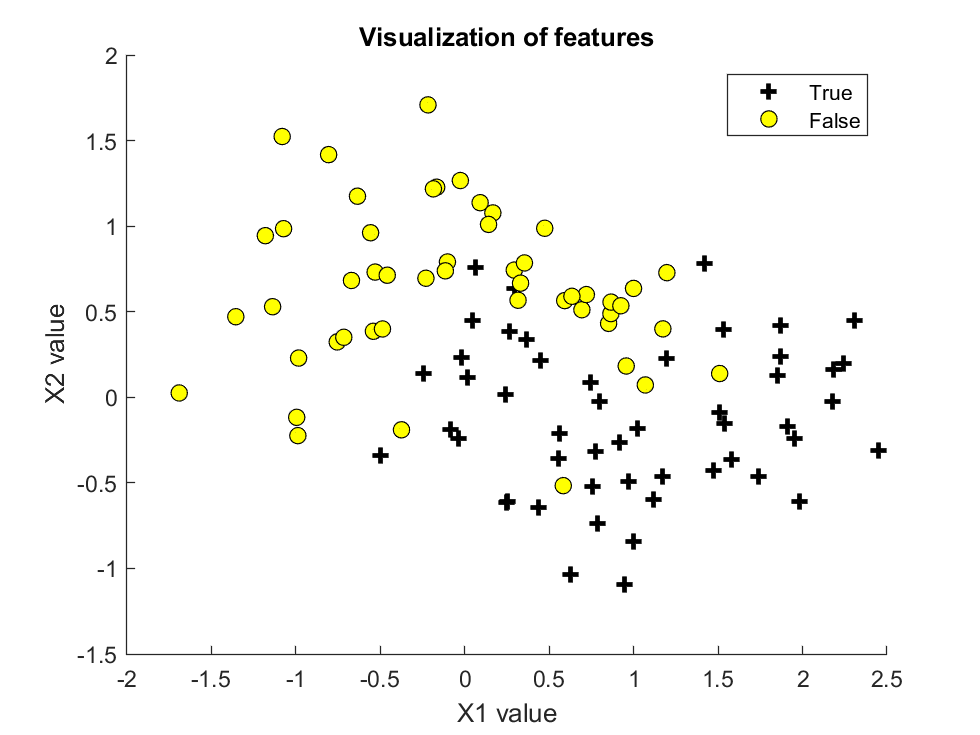

% Visualize data points
plotData(X, y, 'X1 value', 'X2 value');

### Split into train and cross-validation dataset

For the further processing, we split our dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X, y);

### Initialize parameters

% Setup the parameters
input_layer_size  = size(X_train, 2); % Number of features in dataset
hidden_layer_size = 50;               % 50 hidden units
num_labels = 2;                       % 2 labels, from 1 to 2

% Randomly initialize theta
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

We now can train our neuronal network, using the development dataset.

### Train neuronal network

% Set options
options = optimset('MaxIter', 50, 'PlotFcns', @optimplotfval);

%  Set regularization
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, ...
    input_layer_size, ...
    hidden_layer_size, ...
    num_labels, X_train, y_train, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
    hidden_layer_size, (input_layer_size + 1));

Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
    num_labels, (hidden_layer_size + 1));

With the help of the received thetas we can now classify data from the cross-validation set and assess the quality of the classification.

### Predict data

pred = predict(Theta1, Theta2, X_val);

### Statistics for the evaluation of the model

Various metrics are used to assess the quality of the model.

#### Confusion Matrix

% Compute confusion matrix on our development set
cm = confusionmatrix(pred, y_val);

cm =      9     1
     0    10


disp(['Cross-validation Confusion Matrix:' newline, ...
    '[' num2str(cm(:).') ']']);

Cross-validation Confusion Matrix:
[9   0   1  10]


#### Accuracy

% Compute accuracy on our development set
a = overallAccuracy(pred, y_val);

fprintf('Cross-validation Accuracy (percentage): %f\n', a);

Cross-validation Accuracy (percentage): 95.000000


#### Precision

% Compute precision on our development set
p = precision(pred, y_val, 1);

fprintf('Cross-validation Precision: %f\n', p);

Cross-validation Precision: 1.000000


#### Recall

% Compute recall on our development set
r = recall(pred, y_val, 1);

fprintf('Cross-validation Recall: %f\n', r);

Cross-validation Recall: 0.900000


## **Model 1: Using one layer and multiple features, non regularized**

In this first model we use most of the features from the dataset to train our neural network. We do not regularize the model at this time.

### Load traing data

The data used for the training phase will be read from a given file *house_train*`.csv`. The description of the data and their origin is not part of this assignment. Below the first five rows will be displayed:

% Load tain data
train_data_ordered = importHouseData('house_train.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name     price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ______________

 As we will split the data later in a training and a cross validation part, we have to randomly order the data. The values of the feature *object_type* are coded numerically.

% Randomly order data
train_data = train_data_ordered(randperm(size(train_data_ordered,1)),:);

% Initialize variables
X = double(table2array(train_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));

% Categorize categorical value object_type
y_raw = table2array(train_data(:, {'object_type_name'}) );

% Categorize categorical value object_type
% Wohnung = 1;
% Sonstiges = 2;
% Einfamilienhaus = 3;
% Mehrfamilienhaus = 4;
y = categorizeData(y_raw);

Before we can train our network, we first have to bring our features on a similar scale using feature normalization:

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);
X_norm = [ones(size(X_norm,1), 1), X_norm];

### Split into train and cross-validation dataset

For the further processing, we split our dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X_norm, y);

### Initialize parameters

As a first approach we choose one layer and a number of 50 nodes per hidden layer.

% Setup the parameters
input_layer_size  = size(X_train, 2); % Number of features in dataset
hidden_layer_size = 50;               % 50 hidden units
num_labels = 4;                       % 4 Labels

% Randomly initialize theta
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

### Train neuronal network

% Set options
options = optimset('MaxIter', 50, 'PlotFcns', @optimplotfval);

%  Disable regularization
lambda = 0;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, ...
    input_layer_size, ...
    hidden_layer_size, ...
    num_labels, X_train, y_train, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
    hidden_layer_size, (input_layer_size + 1));

Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
    num_labels, (hidden_layer_size + 1));

### Predict data

pred = predict(Theta1, Theta2, X_val);

### Statistics for the evaluation of the model

Various metrics are used to assess the quality of the model.

% Compute confusion matrix on our train set
cm = confusionmatrix(pred, y_val);

cm =         1270           0         137          18
         102           1         140          13
         131           2        1189          33
          68           1         323          70


% Compute accuracy on our train set
a = overallAccuracy(pred, y_val);

% Print metrics
printCvMetrics(pred, y_val, cm, a);

Cross-validation Confusion Matrix:
[1270   102   131    68     0     1     2     1   137   140  1189   323    18    13    33    70]
Cross-validation Accuracy (%): 72.327

Cross-validation Precision, Wohnung: 0.8084
Cross-validation Recall, Wohnung: 0.89123
Cross-validation F score, Wohnung: 0.8478

Cross-validation Precision, Sonstiges: 0.25
Cross-validation Recall, Sonstiges: 0
Cross-validation F score, Sonstiges: 0

Cross-validation Precision, Einfamilienhaus: 0.66462
Cross-validation Recall, Einfamilienhaus: 0.10111
Cross-validation F score, Einfamilienhaus: 0.17551

Cross-validation Precision, Mehrfamilienhaus: 0.52239
Cross-validation Recall, Mehrfamilienhaus: 0.038961
Cross-validation F score, Mehrfamilienhaus: 0.072514


### Apply model to test data

The optimized model can now be applied to the test dataset. The data is located in the file *house_test.csv*.

% Load test data
test_data_ordered = importHouseData('house_test.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    _______________

% Randomly order data
test_data = test_data_ordered(randperm(size(test_data_ordered,1)),:);

% Initialize variables
X = double(table2array(test_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));

% Categorize categorical value object_type
y_raw = table2array(test_data(:, {'object_type_name'}) );

% Categorize categorical value object_type
% Wohnung = 1;
% Sonstiges = 2;
% Einfamilienhaus = 3;
% Mehrfamilienhaus = 4;
y = categorizeData(y_raw);

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);
X_norm = [ones(size(X_norm,1), 1), X_norm];

% Predict data
pred = predict(Theta1, Theta2, X_norm);

In order to judge the quality of the model, we can again calculate some metrics:

% Compute confusion matrix on our test set
cm = confusionmatrix(pred, y);

cm =         1780           4         238          33
         150           2         214          21
         160           1        1757          32
         105           0         474         109


% Compute accuracy on our test set
a = overallAccuracy(pred, y);

% Print metrics
printTestMetrics(pred, y, cm, a);

Test Confusion Matrix:
[1780   150   160   105     4     2     1     0   238   214  1757   474    33    21    32   109]
Test Accuracy (%): 71.811

Test Precision, Wohnung: 0.81093
Test Recall, Wohnung: 0.86618
Test F score, Wohnung: 0.83765

Test Precision, Sonstiges: 0.28571
Test Recall, Sonstiges: 0.010336
Test F score, Sonstiges: 0.01995

Test Precision, Einfamilienhaus: 0.65486
Test Recall, Einfamilienhaus: 0.12205
Test F score, Einfamilienhaus: 0.20575

Test Precision, Mehrfamilienhaus: 0.55897
Test Recall, Mehrfamilienhaus: 0.047965
Test F score, Mehrfamilienhaus: 0.088349


## **Model 2: Adding additional layer and increase # of hidden units**

Next we will train a new model with an additional hidden layer. This should allow the model to make more accurate classifications.

### Load traing data

The data used for the training phase will be read from a given file *house_train*`.csv`. Below the first five rows will be displayed:

% Load tain data
train_data_ordered = importHouseData('house_train.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name     price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ______________

 As we will split the data later in a training and a cross validation part, we have to randomly order the data.

% Randomly order data
train_data = train_data_ordered(randperm(size(train_data_ordered,1)),:);

% Initialize variables
X = double(table2array(train_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));

% Load categorical value object_type
y_raw = table2array(train_data(:, {'object_type_name'}) );

% Map categorical value object_type
% Wohnung = 1;
% Sonstiges = 2;
% Einfamilienhaus = 3;
% Mehrfamilienhaus = 4;
y = categorizeData(y_raw);

Before we can train our network, we first have to bring our features on a similar scale using feature normalization:

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);
X_norm = [ones(size(X_norm,1), 1), X_norm];

### Split into train and cross-validation dataset

For the further processing, we split our dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X_norm, y);

### Initialize parameters

Compared to the last model we increase the number of layers and the size of the units per layer:

% Setup the parameters
input_layer_size  = size(X_train, 2); % Number of features in dataset
hidden_layer_size = 100;              % 100 hidden units
num_labels = 4;                       % 4 Labels

% Randomly initialize theta
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, hidden_layer_size);
initial_Theta3 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:); initial_Theta3(:) ];

### Train neuronal network

% Set options
options = optimset('MaxIter', 70, 'PlotFcns', @optimplotfval);

%  Disable regularization
lambda = 0;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnnCostFunction(p, ...
    input_layer_size, ...
    hidden_layer_size, ...
    num_labels, X_train, y_train, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);
% Obtain thets back from nn_params
[Theta1, Theta2, Theta3] = reshapeThetaNNN(nn_params, ...
    input_layer_size, ...
    hidden_layer_size, ...
    num_labels);

### Predict data

pred = predictNN(Theta1, Theta2, Theta3, X_val);

### Statistics for the evaluation of the model

Various metrics are used to assess the quality of the model. When looking at the confusion matrix, it is noticeable that with several layers in the category "Sonstiges"  no value could be correctly predicted.

% Compute confusion matrix on our train set
cm = confusionmatrix(pred, y_val);

cm =         1285           0         136          20
         114           0         135          17
         134           0        1148          41
          79           0         315          74


% Compute accuracy on our train set
a = overallAccuracy(pred, y_val);

% Print metrics
printCvMetrics(pred, y_val, cm, a);

Cross-validation Confusion Matrix:
[1285   114   134    79     0     0     0     0   136   135  1148   315    20    17    41    74]
Cross-validation Accuracy (%): 71.6695

Cross-validation Precision, Wohnung: 0.79715
Cross-validation Recall, Wohnung: 0.89174
Cross-validation F score, Wohnung: 0.84179

Cross-validation Precision, Sonstiges: NaN
Cross-validation Recall, Sonstiges: 0
Cross-validation F score, Sonstiges: NaN

Cross-validation Precision, Einfamilienhaus: 0.66205
Cross-validation Recall, Einfamilienhaus: 0.1028
Cross-validation F score, Einfamilienhaus: 0.17796

Cross-validation Precision, Mehrfamilienhaus: 0.48684
Cross-validation Recall, Mehrfamilienhaus: 0.042735
Cross-validation F score, Mehrfamilienhaus: 0.078573


### Apply model to test data

The optimized model can now be applied to the test dataset. The data is located in the file *house_test.csv*.

% Load test data
test_data_ordered = importHouseData('house_test.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    _______________

% Randomly order data
test_data = test_data_ordered(randperm(size(test_data_ordered,1)),:);

% Initialize variables
X = double(table2array(test_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));

% Binarize categorical value object_type
y_raw = table2array(test_data(:, {'object_type_name'}) );

% Binarize categorical value object_type
% Wohnung = 1;
% Sonstiges = 2;
% Einfamilienhaus = 3;
% Mehrfamilienhaus = 4;
y = categorizeData(y_raw);

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);
X_norm = [ones(size(X_norm,1), 1), X_norm];

In order to judge the quality of the model, we can again calculate some metrics:

% Predict data
pred = predictNN(Theta1, Theta2, Theta3, X_norm);
% Compute confusion matrix on our test set
cm = confusionmatrix(pred, y);

cm =         1781           0         229          45
         151           0         217          19
         178           0        1726          46
         107           0         459         122


% Compute accuracy on our test set
a = overallAccuracy(pred, y);

% Print metrics
printTestMetrics(pred, y, cm, a);

Test Confusion Matrix:
[1781   151   178   107     0     0     0     0   229   217  1726   459    45    19    46   122]
Test Accuracy (%): 71.437

Test Precision, Wohnung: 0.80334
Test Recall, Wohnung: 0.86667
Test F score, Wohnung: 0.8338

Test Precision, Sonstiges: NaN
Test Recall, Sonstiges: 0
Test F score, Sonstiges: NaN

Test Precision, Einfamilienhaus: 0.65602
Test Recall, Einfamilienhaus: 0.11744
Test F score, Einfamilienhaus: 0.19921

Test Precision, Mehrfamilienhaus: 0.52586
Test Recall, Mehrfamilienhaus: 0.065407
Test F score, Mehrfamilienhaus: 0.11634


## **Model 3: Adding third hidden layer and regularization**

As final model we will add another hidden layer and use regularization to prevent from overfitting.

### Load traing data

The data used for the training phase will be read from a given file *house_train*`.csv`. Below the first five rows will be displayed:

% Load tain data
train_data_ordered = importHouseData('house_train.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name     price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ______________

 As we will split the data later in a training and a cross validation part, we have to randomly order the data.

% Randomly order data
train_data = train_data_ordered(randperm(size(train_data_ordered,1)),:);

% Initialize variables
X = double(table2array(train_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));

% Load categorical value object_type
y_raw = table2array(train_data(:, {'object_type_name'}) );

% Map categorical value object_type
% Wohnung = 1;
% Sonstiges = 2;
% Einfamilienhaus = 3;
% Mehrfamilienhaus = 4;
y = categorizeData(y_raw);

Before we can train our network, we first have to bring our features on a similar scale using feature normalization:

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);
X_norm = [ones(size(X_norm,1), 1), X_norm];

### Split into train and cross-validation dataset

For the further processing, we split our dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X_norm, y);

### Initialize parameters

% Setup the parameters
input_layer_size  = size(X_train, 2); % Number of features in dataset
hidden_layer_size = 20;               % 20 hidden units
num_labels = 4;                       % 4 Labels

% Randomly initialize theta
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, hidden_layer_size);
initial_Theta3 = randInitializeWeights(hidden_layer_size, hidden_layer_size);
initial_Theta4 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:); initial_Theta3(:); initial_Theta4(:) ];

### Train neuronal network

To prevent overfitting, apply regularization this time. We set lambda to 1.

% Set options
options = optimset('MaxIter', 100, 'PlotFcns', @optimplotfval);

% Add regularization
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnnnCostFunction(p, ...
    input_layer_size, ...
    hidden_layer_size, ...
    num_labels, X_train, y_train, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);
% Obtain thets back from nn_params
[Theta1, Theta2, Theta3, Theta4] = reshapeThetaNNNN(nn_params, ...
    input_layer_size, ...
    hidden_layer_size, ...
    num_labels);

### Predict data

pred = predictNNN(Theta1, Theta2, Theta3, Theta4, X_val);

### Statistics for the evaluation of the model

Various metrics are used to assess the quality of the model.

% Compute confusion matrix on our train set
cm = confusionmatrix(pred, y_val);

cm =         1263           0         110          38
         119           0         105          26
         124           0        1190          82
          74           0         257         110


% Compute accuracy on our train set
a = overallAccuracy(pred, y_val);

% Print metrics
printCvMetrics(pred, y_val, cm, a);

Cross-validation Confusion Matrix:
[1263   119   124    74     0     0     0     0   110   105  1190   257    38    26    82   110]
Cross-validation Accuracy (%): 73.2704

Cross-validation Precision, Wohnung: 0.79937
Cross-validation Recall, Wohnung: 0.89511
Cross-validation F score, Wohnung: 0.84453

Cross-validation Precision, Sonstiges: NaN
Cross-validation Recall, Sonstiges: 0
Cross-validation F score, Sonstiges: NaN

Cross-validation Precision, Einfamilienhaus: 0.716
Cross-validation Recall, Einfamilienhaus: 0.078797
Cross-validation F score, Einfamilienhaus: 0.14197

Cross-validation Precision, Mehrfamilienhaus: 0.42969
Cross-validation Recall, Mehrfamilienhaus: 0.086168
Cross-validation F score, Mehrfamilienhaus: 0.14355


### Apply model to test data

The optimized model can now be applied to the test dataset. The data is located in the file *house_test.csv*.

% Load test data
test_data_ordered = importHouseData('house_test.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    _______________

% Randomly order data
test_data = test_data_ordered(randperm(size(test_data_ordered,1)),:);

% Initialize variables
X = double(table2array(test_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));

% Binarize categorical value object_type
y_raw = table2array(test_data(:, {'object_type_name'}) );

% Binarize categorical value object_type
% Wohnung = 1;
% Sonstiges = 2;
% Einfamilienhaus = 3;
% Mehrfamilienhaus = 4;
y = categorizeData(y_raw);

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);
X_norm = [ones(size(X_norm,1), 1), X_norm];

In order to judge the quality of the model, we can again calculate some metrics:

% Predict data
pred = predictNNN(Theta1, Theta2, Theta3, Theta4, X_norm);
% Compute confusion matrix on our test set
cm = confusionmatrix(pred, y);

cm =         1778           0         212          65
         149           0         199          39
         142           0        1717          91
          96           0         425         167


% Compute accuracy on our test set
a = overallAccuracy(pred, y);

% Print metrics
printTestMetrics(pred, y, cm, a);

Test Confusion Matrix:
[1778   149   142    96     0     0     0     0   212   199  1717   425    65    39    91   167]
Test Accuracy (%): 72.0866

Test Precision, Wohnung: 0.82125
Test Recall, Wohnung: 0.86521
Test F score, Wohnung: 0.84265

Test Precision, Sonstiges: NaN
Test Recall, Sonstiges: 0
Test F score, Sonstiges: NaN

Test Precision, Einfamilienhaus: 0.67254
Test Recall, Einfamilienhaus: 0.10872
Test F score, Einfamilienhaus: 0.18718

Test Precision, Mehrfamilienhaus: 0.46133
Test Recall, Mehrfamilienhaus: 0.094477
Test F score, Mehrfamilienhaus: 0.15683
